# **COMPARAISON PREOPERATOIRE-POSTOPERATOIRE (appareillés)**

% ANALYSE COMPARATIVE DES SYNERGIES MUSCULAIRES  
% Chargement des données
W_pre = Profilglobalsynergiespr; % Groupe pre-opératoire (9 sujets)
W_post = Profilglobalsynergiespost;    % Groupe post-opératoire (9 sujets)

noms_muscles = {'Ant. deltoid', 'Mid. deltoid', 'post. deltoid', ...
                'Mid. trapezius', 'Up. trapezius', 'Ant. serratus'};

% Nombre de sujets dans chaque groupe
n_pre = 9;
n_post = 9;

% ---- EXTRACTION DES SYNERGIES ----
synergy1_pre = zeros(6, n_pre);
synergy2_pre = zeros(6, n_pre);
for i = 1:n_pre
    synergy1_pre(:, i) = W_pre(:, (i-1)*2 + 1);
    synergy2_pre(:, i) = W_pre(:, (i-1)*2 + 2);
end

synergy1_post = zeros(6, n_post);
synergy2_post = zeros(6, n_post);
for i = 1:n_post
    synergy1_post(:, i) = W_post(:, (i-1)*2 + 1);
    synergy2_post(:, i) = W_post(:, (i-1)*2 + 2);
end

% ---- STATISTIQUES DESCRIPTIVES ----
t_val_pre = tinv(0.975, n_pre-1);
t_val_post = tinv(0.975, n_post-1);

mean_synergy1_pre = mean(synergy1_pre, 2);
std_synergy1_pre = std(synergy1_pre, 0, 2);
sem_synergy1_pre = std_synergy1_pre / sqrt(n_pre);
IC_synergy1_pre = t_val_pre * sem_synergy1_pre;

mean_synergy2_pre = mean(synergy2_pre, 2);
std_synergy2_pre = std(synergy2_pre, 0, 2);
sem_synergy2_pre = std_synergy2_pre / sqrt(n_pre);
IC_synergy2_pre = t_val_pre * sem_synergy2_pre;

mean_synergy1_post = mean(synergy1_post, 2);
std_synergy1_post = std(synergy1_post, 0, 2);
sem_synergy1_post = std_synergy1_post / sqrt(n_post);
IC_synergy1_post = t_val_post * sem_synergy1_post;

mean_synergy2_post = mean(synergy2_post, 2);
std_synergy2_post = std(synergy2_post, 0, 2);
sem_synergy2_post = std_synergy2_post / sqrt(n_post);
IC_synergy2_post = t_val_post * sem_synergy2_post;

% ---- TESTS STATISTIQUES AVEC VÉRIFICATION DES CONDITIONS ----
p_values_synergy1 = zeros(6, 1);
p_values_synergy2 = zeros(6, 1);
test_used_synergy1 = strings(6, 1);
test_used_synergy2 = strings(6, 1);

for muscle = 1:6
    % Pour la synergie 1
    data_pre = synergy1_pre(muscle, :)';
    data_post = synergy1_post(muscle, :)';
    differences = data_pre - data_post;  % Calcul des différences pour tests appareillés
    
    % Test de normalité sur les différences
    p_sw_diff = swtest(differences, 0.05);
    normal_diff = all(~isnan(differences)) && (length(differences) > 3) && (p_sw_diff > 0.05);
    
    fprintf('\n--- Muscle %s (Synergie 1) ---\n', noms_muscles{muscle});
    fprintf('Normalité des différences : p = %.3f (%s)\n', p_sw_diff, ternary(p_sw_diff < 0.05, 'non normal', 'normal'));
    
    if normal_diff
        [~, p_values_synergy1(muscle)] = ttest(data_pre, data_post);  % Test t apparié
        test_used_synergy1(muscle) = "t-test apparié";
    else
        p_values_synergy1(muscle) = signrank(data_pre, data_post);    % Test de Wilcoxon
        test_used_synergy1(muscle) = "Wilcoxon";
    end
    fprintf('→ Test utilisé : %s\n', test_used_synergy1(muscle));
    
    % Pour la synergie 2
    data_pre = synergy2_pre(muscle, :)';
    data_post = synergy2_post(muscle, :)';
    differences = data_pre - data_post;
    
    p_sw_diff = swtest(differences, 0.05);
    normal_diff = all(~isnan(differences)) && (length(differences) > 3) && (p_sw_diff > 0.05);
    
    fprintf('\n--- Muscle %s (Synergie 2) ---\n', noms_muscles{muscle});
    fprintf('Normalité des différences : p = %.3f (%s)\n', p_sw_diff, ternary(p_sw_diff < 0.05, 'non normal', 'normal'));
    
    if normal_diff
        [~, p_values_synergy2(muscle)] = ttest(data_pre, data_post);  % Test t apparié
        test_used_synergy2(muscle) = "t-test apparié";
    else
        p_values_synergy2(muscle) = signrank(data_pre, data_post);    % Test de Wilcoxon
        test_used_synergy2(muscle) = "Wilcoxon";
    end
    fprintf('→ Test utilisé : %s\n', test_used_synergy2(muscle));
end


--- Muscle Ant. deltoid (Synergie 1) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle Ant. deltoid (Synergie 2) ---


Normalité des différences : p = 1.000 (normal)


→ Test utilisé : t-test apparié



--- Muscle Mid. deltoid (Synergie 1) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle Mid. deltoid (Synergie 2) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle post. deltoid (Synergie 1) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle post. deltoid (Synergie 2) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle Mid. trapezius (Synergie 1) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle Mid. trapezius (Synergie 2) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle Up. trapezius (Synergie 1) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle Up. trapezius (Synergie 2) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle Ant. serratus (Synergie 1) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



--- Muscle Ant. serratus (Synergie 2) ---


Normalité des différences : p = 0.000 (non normal)


→ Test utilisé : Wilcoxon



n_param_sy1 = sum(test_used_synergy1 == "t-test apparié");
n_nonparam_sy1 = sum(test_used_synergy1 == "Wilcoxon");
n_param_sy2 = sum(test_used_synergy2 == "t-test apparié");
n_nonparam_sy2 = sum(test_used_synergy2 == "Wilcoxon");

fprintf('\n=== Vérification des conditions statistiques ===\n');


=== Vérification des conditions statistiques ===


fprintf('Les hypothèses de normalité ont été testées via le test de Shapiro-Wilk (swtest) sur les différences pré-post pour tests appareillés.\n');

Les hypothèses de normalité ont été testées via le test de Shapiro-Wilk (swtest) sur les différences pré-post pour tests appareillés.


fprintf('Lorsque la normalité n''était pas vérifiée, des tests non paramétriques (Wilcoxon) ont été utilisés.\n');

Lorsque la normalité n'était pas vérifiée, des tests non paramétriques (Wilcoxon) ont été utilisés.


fprintf('Les types de tests appliqués sont résumés pour chaque muscle et chaque synergie.\n');

Les types de tests appliqués sont résumés pour chaque muscle et chaque synergie.


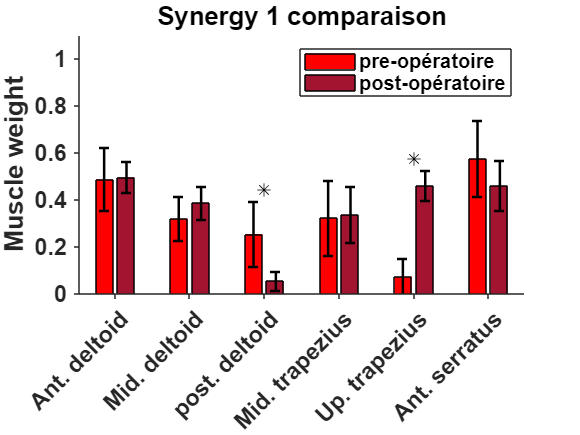


% ---- VISUALISATIONS ----
% 1. Comparaison des synergies 1 entre groupes
figure;
x = 1:6;
% Correction ici: créer une matrice avec les deux vecteurs comme colonnes
data_to_plot = [mean_synergy1_pre, mean_synergy1_post];
b = bar(x, data_to_plot);
b(1).FaceColor = 'r';
b(2).FaceColor = [0.6350 0.0780 0.1840];
hold on

% Ajout des barres d'erreur (IC 95%)
% Positions ajustées pour les barres d'erreur
x1 = x - 0.15;
x2 = x + 0.15;
errorbar(x1, mean_synergy1_pre, IC_synergy1_pre, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(x2, mean_synergy1_post, IC_synergy1_post, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

% Signification statistique
for i = 1:6
    if p_values_synergy1(i) < 0.05
        plot(i, max([mean_synergy1_pre(i)+IC_synergy1_pre(i), mean_synergy1_post(i)+IC_synergy1_post(i)])+0.05, '*k', 'MarkerSize', 8);
    end
end

title('Synergy 1 comparaison', 'FontSize', 18, 'FontWeight', 'bold');
ylabel('Muscle weight', 'FontSize', 14);
xticks(1:6);
xticklabels(noms_muscles);
xtickangle(45);
ylim([0 1.1]);
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out', 'Box', 'off');
legend({'pre-opératoire', 'post-opératoire'}, 'Location', 'northeast', 'FontSize', 12);
hold off;

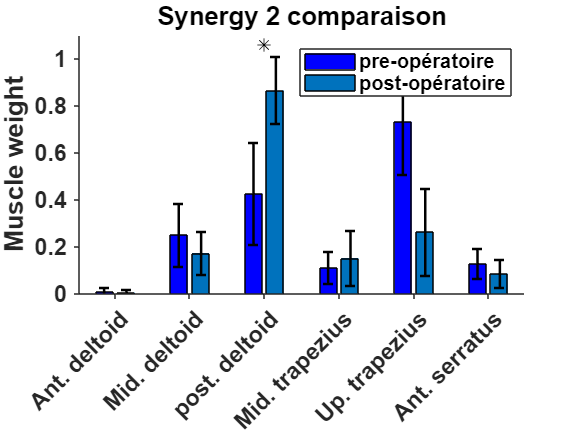


% 2. Comparaison des synergies 2 entre groupes
figure;
% Correction similaire pour la deuxième synergie
data_to_plot2 = [mean_synergy2_pre, mean_synergy2_post];
b = bar(x, data_to_plot2);
b(1).FaceColor = 'b';
b(2).FaceColor = [0 0.4470 0.7410];
hold on

% Ajout des barres d'erreur (IC 95%)
errorbar(x1, mean_synergy2_pre, IC_synergy2_pre, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);
errorbar(x2, mean_synergy2_post, IC_synergy2_post, 'k', 'LineStyle', 'none', 'LineWidth', 1.5);

% Signification statistique
for i = 1:6
    if p_values_synergy2(i) < 0.05
        plot(i, max([mean_synergy2_pre(i)+IC_synergy2_pre(i), mean_synergy2_post(i)+IC_synergy2_post(i)])+0.05, '*k', 'MarkerSize', 8);
    end
end

title('Synergy 2 comparaison', 'FontSize', 18, 'FontWeight', 'bold');
ylabel('Muscle weight', 'FontSize', 14);
xticks(1:6);
xticklabels(noms_muscles);
xtickangle(45);
ylim([0 1.1]);
set(gca, 'FontSize', 14, 'FontWeight', 'bold', 'TickDir', 'out', 'Box', 'off');
legend({'pre-opératoire', 'post-opératoire'}, 'Location', 'northeast', 'FontSize', 12);
hold off;


% Comptage des types de tests utilisés
n_param_sy1 = sum(test_used_synergy1 == "t-test apparié");
n_nonparam_sy1 = sum(test_used_synergy1 == "Wilcoxon");
n_param_sy2 = sum(test_used_synergy2 == "t-test apparié");
n_nonparam_sy2 = sum(test_used_synergy2 == "Wilcoxon");

%% 4. Tableau récapitulatif des p-values
% Ajouter des astérisques pour les p-values < 0.05
highlight = @(p) sprintf('%.3f%s', p, ternary(p < 0.05, ' *', ''));

% Appliquer la fonction à chaque valeur
synergy1_str = arrayfun(@(p) highlight(p), p_values_synergy1, 'UniformOutput', false);
synergy2_str = arrayfun(@(p) highlight(p), p_values_synergy2, 'UniformOutput', false);

% Créer une table de chaînes
T_str = table(synergy1_str(:), synergy2_str(:), ...
              'VariableNames', {'Synergie_1', 'Synergie_2'}, ...
              'RowNames', noms_muscles);

% Affichage
disp('=== Tableau des p-values par muscle ( * : p < 0.05 ) ===');

=== Tableau des p-values par muscle ( * : p < 0.05 ) ===


disp(T_str);

                      Synergie_1     Synergie_2 
                      ___________    ___________

    Ant. deltoid      {'0.820'  }    {'0.796'  }
    Mid. deltoid      {'0.250'  }    {'0.496'  }
    post. deltoid     {'0.027 *'}    {'0.012 *'}
    Mid. trapezius    {'0.910'  }    {'0.910'  }
    Up. trapezius     {'0.004 *'}    {'0.012 *'}
    Ant. serratus     {'0.301'  }    {'0.359'  }




%% 5. Corrélation entre les profils
% Calculer les corrélations entre les profils des deux groupes
corr_synergy1 = corrcoef(mean_synergy1_pre, mean_synergy1_post);
corr_synergy2 = corrcoef(mean_synergy2_pre, mean_synergy2_post);

% Afficher les résultats avec interprétation
fprintf('\n=== Corrélation entre les profils de synergies ===\n');


=== Corrélation entre les profils de synergies ===


fprintf('Synergie 1 : r = %.3f\n', corr_synergy1(1,2));

Synergie 1 : r = 0.299


if corr_synergy1(1,2) > 0.7
    fprintf('→ Forte similarité entre les profils de la Synergie 1 (post-opératoires vs pre-opératoires).\n');
elseif corr_synergy1(1,2) > 0.4
    fprintf('→ Similarité modérée entre les profils de la Synergie 1.\n');
else
    fprintf('→ Faible similarité entre les profils de la Synergie 1.\n');
end

→ Faible similarité entre les profils de la Synergie 1.



fprintf('Synergie 2 : r = %.3f\n', corr_synergy2(1,2));

Synergie 2 : r = 0.503


if corr_synergy2(1,2) > 0.7
    fprintf('→ Forte similarité entre les profils de la Synergie 2 (post-opératoires vs pre-opératoires).\n');
elseif corr_synergy2(1,2) > 0.4
    fprintf('→ Similarité modérée entre les profils de la Synergie 2.\n');
else
    fprintf('→ Faible similarité entre les profils de la Synergie 2.\n');
end

→ Similarité modérée entre les profils de la Synergie 2.
